# Mess- und Regelungstechnik - Praktikum 6

Prof. Dr.-Ing. Anselm Haselhoff - Hochschule Ruhr West

## Aufgabe 1

Es soll die Vertikaldynamik eines Fahrzeuges modelliert werden. Zunächst wird nur ein Teilbereich (Feder-Masse-Dämpfer-System mit Kraftanregung für Dynamik zwischen Fahrzeugaufbau und Rad) gemäß Abb. 1 betrachtet.

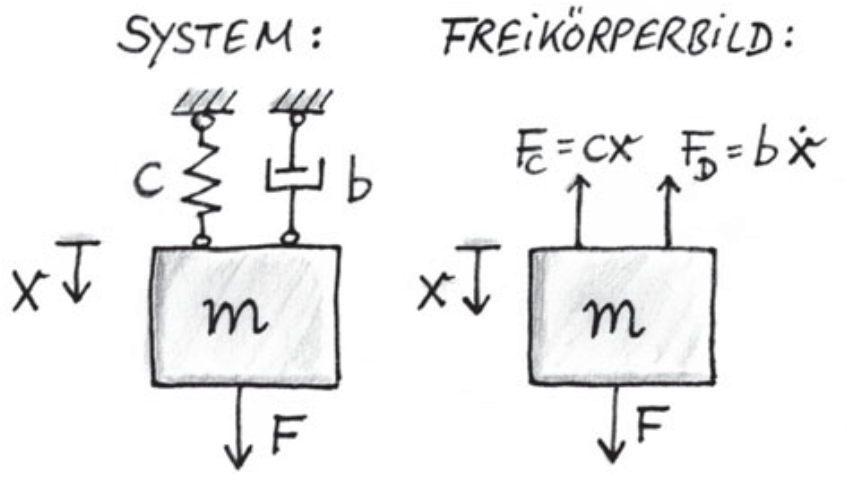

Abbildung 1: Feder-Masse-Dämpfer mit Kraftanregung [Tieste and Romberg, 2012].

### 1)

Öffnen Sie ein leeres Simulink Model und nehmen Sie zunächst folgende Konfigurationen unter *Modelling > Model Settings* vor:

*> Solver*

*    > Solver Selection*

**        Type**: Fixed-step

**        Solver**: ode4

*    > Solver Details*

        **Fixed-step size**: 0.01

*> Data Import/Export*

*    > Save to workspace or file*

        **States**: [x] - **Format**: Array

### 2)

Bauen Sie das Feder-Masse-Dämpfer-System entsprechend Abb. 2 auf.

*Hinweis: Es wurden die mechanischen Bauteile aus der Library *Simscape > Foundation Library > Mechanical* und die Simulink-Komponenten "Solver Configuration", "PS-Simulink-Converter", "Simulink-PS-Converter", "Scope", "Step", "Pulse" und "Sum" verwendet.*

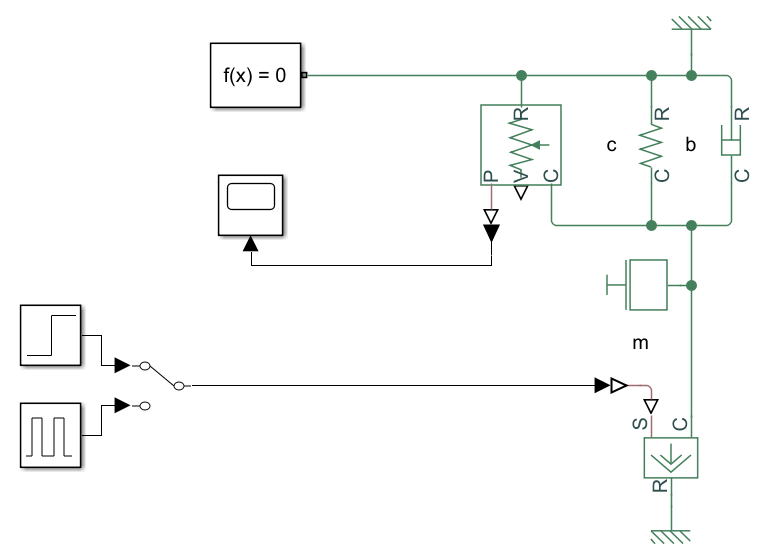

Abbildung 2: Feder-Masse-Dämpfer-System mit Kraftanregung in Simulink und Simscape

### 2)

Geben Sie eine Masse von m = $100kg$, Federkonstante von c = $1000\frac{N}{m}$ und Dämpfungskonstante von b = $50\frac{N}{m/s}$ an. Stellen Sie beim Step- und Pulse-Block außerdem einen **Final value** bzw. eine **Amplitude** von 1000 ein.

### 3)

Starten Sie die Simulation und versichern Sie sich, dass die Sprungantwort des Scopes in `out.xout(:, 2)` im Workspace gespeichert ist (z. B. mit `plot(out.xout(:,2))`).

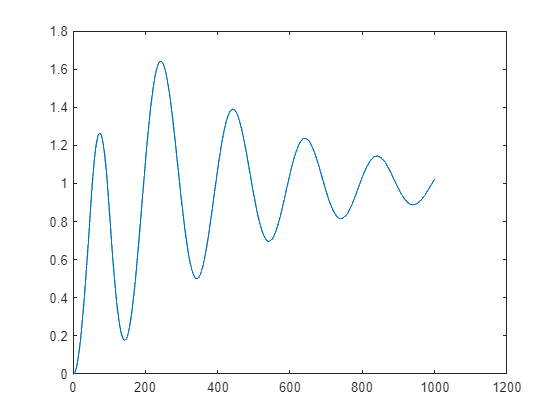

plot(out.xout(:,2));

## Aufgabe 2

### 1)

Öffnen Sie in MATLAB unter *Apps* den "PID Tuner". Importieren Sie die Simulation durch folgende Schritte:

- Wählen Sie *Plant > Type > PID*.

- Öffnen Sie *Plant > Identify New Plant*.

- Wechseln Sie zu *Plant Identification* und wählen Sie *Get I/O Data > Step Response*.

- Geben Sie für **Output** `out.xout(:,2)`, **Amplitude** $1000$, **Onset Lag** $1$ und **Sample Time** $0.01(s)$ an. (Dies enspricht den Werten aus der Konfiguration des Step-Blocks, bzw. des Models aus Aufgabe 1.)

- Importieren Sie die Aufnahme.

- Wählen Sie nun *Structure > Underdamped Pair*.

- Lassen Sie die Strecke mit *Auto estimate > Initialize and Estimate* analysieren. Die Kurven "Identification Data" und "Identified Plant" in der rechten Grafik solten nun identisch sein.

- Wenden Sie die ermittelte Konfiguration mit *Apply* an.

- Wechseln Sie zurück zu *PID Tuner* und lassen Sie sich unter *Show Parameters* die Parameter `Kp, Ki, Kd` des PID-Reglers anzeigen.

## Aufgabe 3

Der PID-Regler kann nun als Steuerelement in das Blockschaltbild implementiert werden, um eine günstigere Strungantwort zu erhalten.

### 1)

Ändern Sie Ihr Model so, dass die "Ideal Force Source" nun anstatt der Strungfunktion den Ausgabewert eines PID-Controllers als Eingang erhält. Der PID-Controller wiederum erhält als Eingabe die Differenz aus der Ausgabe der Sprungfunktion und des "Ideal Translational Motion Sensor". Nutzen Sie für die Differenz den Block "Sum" bspw. mit **List of signs**: -+|.

### 2)

Stellen Sie beim PID-Regler die Parameter aus Aufgabe 2 ein.

### 3)

Starten Sie die Simulation erneut und vergleichen Sie die Sprungantworten.

### 4)

Stellen Sie den Schalter auf den Pulsgenerator und vergleichen Sie das Systemverhalten mit und ohne Regler.

*Tipp: Sie können im Kontextmenü des PID-Reglers "Comment Through" wählen, um ihn zu deaktivieren, aber die Verbindung zu erhalten.*